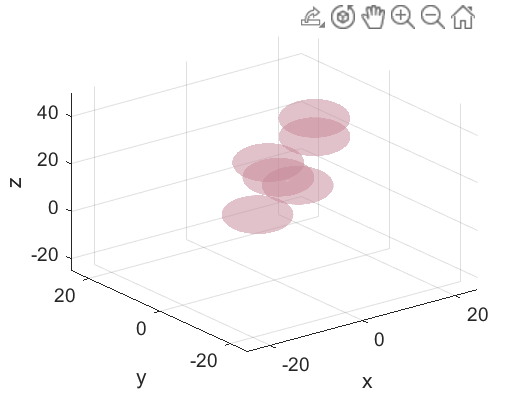

clear all
ax = axes('XLim',[-25 25],'YLim',[-25 25],'ZLim',[-25 50]);
view(3)

R11=6.25;
R31=6.20;

u32=[-0.598;-0.289;0.748];

u33=[0.547;0.373;-0.750];

[x1,y1,z1] = ellipsoid(-0.533,4.10,0,R11,R11,R31,20);
[x2,y2,z2] = ellipsoid(7.60,8.81,8.23,R11,R11,R31,20);


hold on

h(1)=surf(x1,y1,z1,'FaceColor',[200,137,153]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);
g(1)=surf(x2,y2,z2,'FaceColor',[200,137,153]/256, ...
    'EdgeColor','none','FaceAlpha',0.3);

grid on
hold off

t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);

r1 = hgtransform('Parent',ax);
r2 = hgtransform('Parent',ax);
r3 = hgtransform('Parent',ax);

Rz1 = makehgtform('xrotate',-154.2*pi/180);
Ry1 = makehgtform('yrotate',-41.6*pi/180);
Rz2 = makehgtform('xrotate',34.3*pi/180);
Ry2 = makehgtform('yrotate',-138.6*pi/180);
Rz = makehgtform('zrotate',-2*pi/3);

Tz = makehgtform('translate',[0 0 13.97]);

Tr1 = makehgtform('translate',[-0.533 4.10 0]);
Tr2 = makehgtform('translate',[7.60 8.81 8.23]);
Tr3 = makehgtform('translate',[10.88 6.28 0]);

set(h,'Parent',t1);
set(g,'Parent',r1);

h2 = copyobj(h,t2);
h3 = copyobj(h,t3);

g2 = copyobj(g,r2);
g3 = copyobj(g,r3);

set(t1,'Matrix',Tr1*Rz1*Ry1*Rz1/Tr1)
set(t2,'Matrix',Tz*Rz*Tr1*Rz1*Ry1*Rz1/Tr1)
set(t3,'Matrix',(Tz*Rz)^2*Tr1*Rz1*Ry1*Rz1/Tr1)

set(r1,'Matrix',Tr2*Rz2*Ry2*Rz2/Tr2)
set(r2,'Matrix',(Tr3*Tz*Rz/Tr3)*Tr2*Rz2*Ry2*Rz2/Tr2)
set(r3,'Matrix',(Tr3*Tz*Rz/Tr3)^2*Tr2*Rz2*Ry2*Rz2/Tr2)

xlabel('x'); ylabel('y'); zlabel('z')
drawnow

for i = 1:360
   camorbit(1,0,'data',[0 0 1])

   drawnow
end